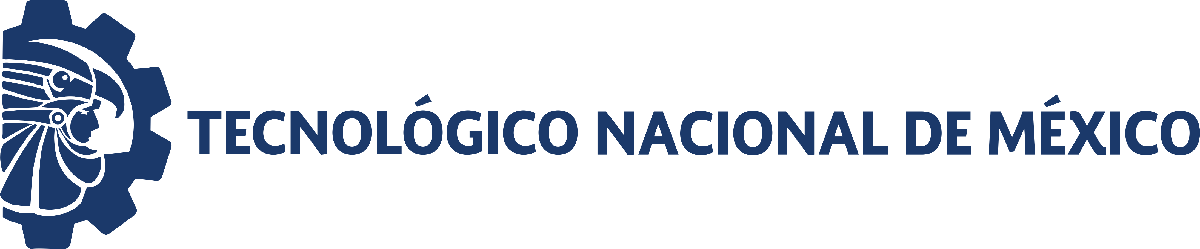                                 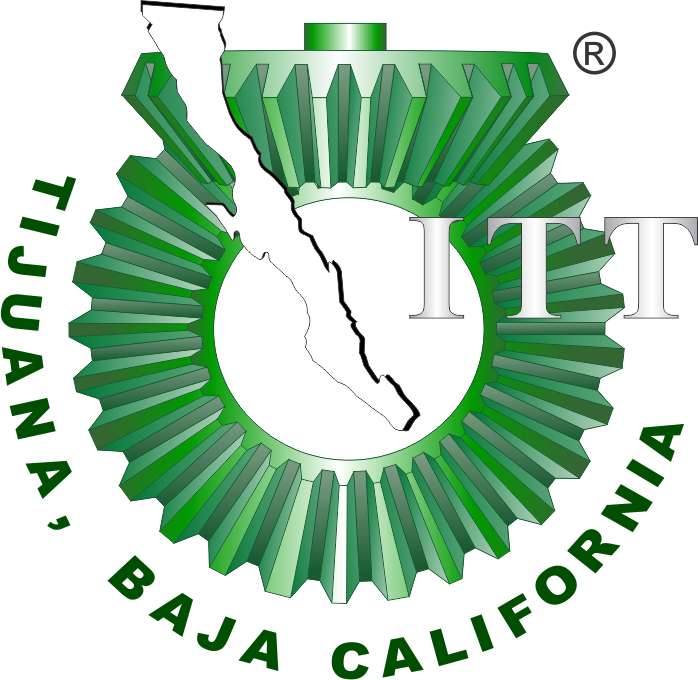

# proyecto: simulación dinámica de un proceso de fermentación mediante un sistema de ecuaciones diferenciales ordinarias

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

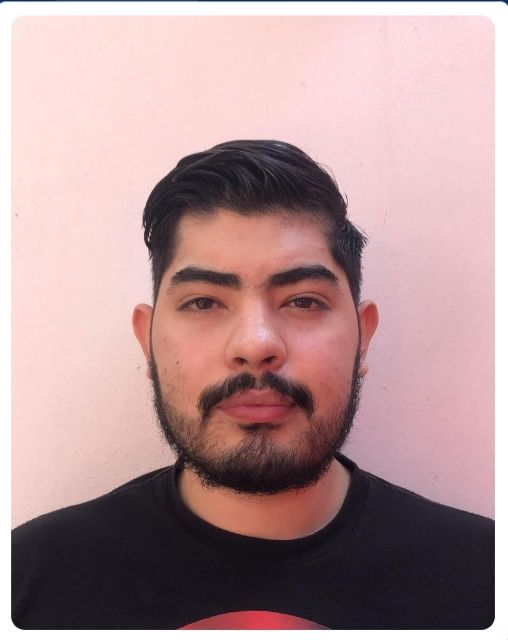

Nombres del alumno: ** Dario Antonio Martinez Camarena**

Número de control: **21210684**

Correo institucional: **l21210684@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo

Desarrollar un gemelo digital basado en ecuaciones diferenciales ordinarias para simular el comportamiento dinámico de un proceso de fermentación, considerando la evolución de la biomasa, el consumo de sustrato y la generación de producto, con el propósito de analizar el comportamiento del sistema y apoyar la toma de decisiones en condiciones simuladas de operación.


$$\frac{dx}{dt}=a_1+a_2y-a_3x-a_4y^2$$



$$\frac{dy}{dt}=b_1+b_2x-b_3y$$



$$\frac{dz}{dt}=c_1yz+c_2z^2-c_3z$$


#### 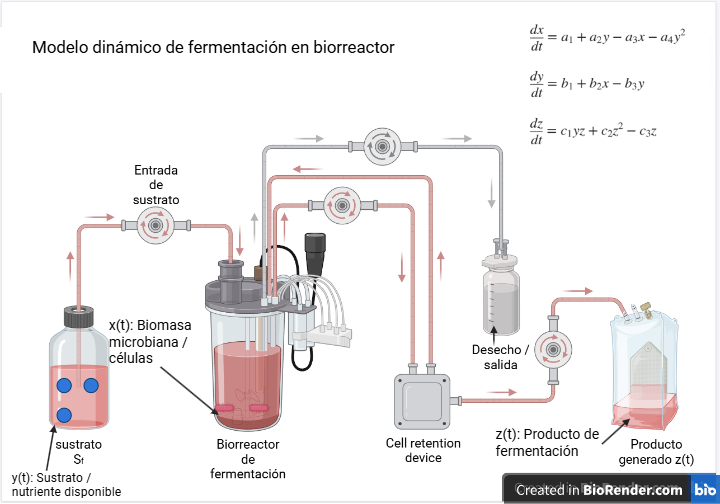

#### Figura. Diagrama representativo del modelo.

## Referencia

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Zhang, B. S., Vanichsriratana, W., Tang, R., Porter, N., & Leigh, J. R. (1997). Modelling and control of fed-batch fermentation processes: towards improved quality and productivity. Transactions of the Institute of Measurement and Control, 19(5), 231–239.

[3] Vanichsriratana, W., Zhang, B. S., & Leigh, J. R. (1997). Optimal control of a fed-batch fermentation process. Transactions of the Institute of Measurement and Control, 19(5), 240–251.

[4] McKay, B., Sanderson, C. S., Willis, M. J., Barford, J. P., & Barton, G. W. (1998). Evolving a hybrid model of a fed-batch fermentation process. Transactions of the Institute of Measurement and Control, 20(1), 4–10.

## Datos experimentales

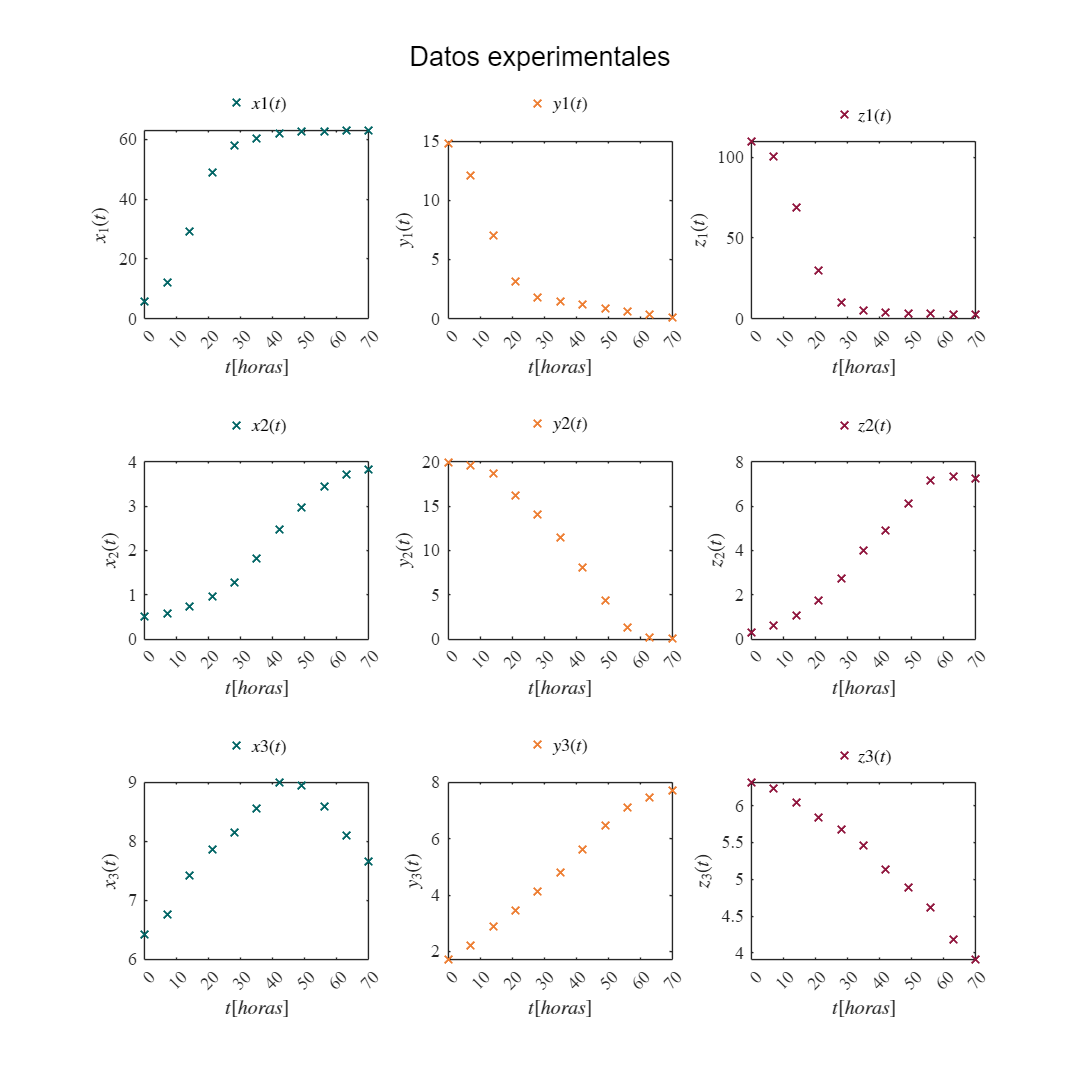

clc; clear; close all; warning('off','all') 
[t,x0,y0,z0,x3,y3,z3] = getdata('data.csv');
plotdataraw(t,x0,y0,z0); sgtitle('Datos experimentales');...
    exportgraphics(gcf,'dataraw.pdf', 'ContentType','vector');

## Datos seleccionados del conjunto 3

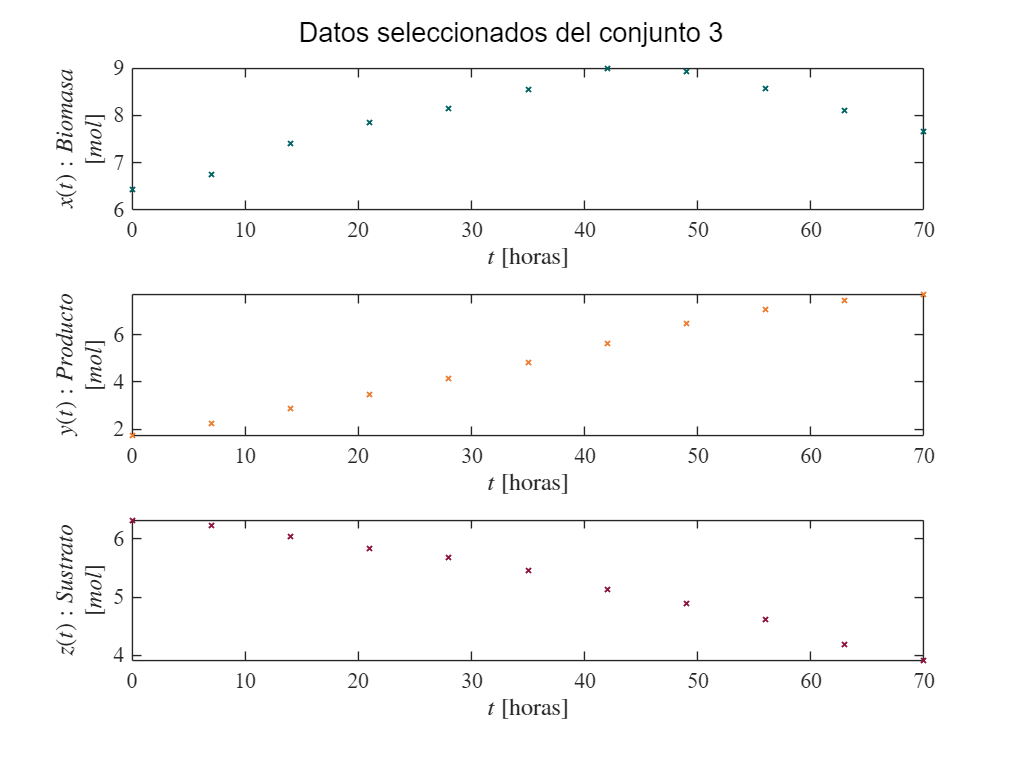

smooth = false; normalize = false;
[t,xo,yo,zo]=getdatanorm('data.csv',smooth,normalize);
plotsys(t,xo,yo,zo); sgtitle('Datos seleccionados del conjunto 3');...
    exportgraphics(gcf,'data_conjunto3.pdf', 'ContentType','vector');

## Modelo obtenido mediante Eureqa


$$\frac{dx}{dt}=a_1+a_2y-a_3x-a_4y^2$$



$$\frac{dy}{dt}=b_1+b_2x-b_3y$$



$$\frac{dz}{dt}=c_1yz+c_2z^2-c_3z$$



$$\frac{dx}{dt}=0.107+0.0296y-0.0104x-0.00531y^2

$$



$$\frac{dy}{dt}=-0.1463+0.0375x-0.0142y$$



$$\frac{dz}{dt}=0.000446099yz+0.00545554z^2-0.0381915z
$$


El modelo dinámico se obtuvo a partir del conjunto de datos seleccionado mediante regresión simbólica en Eureqa. La variable x(t) representa biomasa, y(t) representa producto generado y z(t) representa sustrato disponible. La primera ecuación fue seleccionada de las soluciones generadas por Eureqa, mientras que la segunda y tercera se formularon con estructura biológicamente interpretable debido a la convergencia limitada del software para dichas variables.

## Regresión no lineal y bioestadísticos


clear; close all; clc

smooth = false;
normalize = false;

[t,xo,yo,zo] = getdatanorm('data.csv',smooth,normalize);

P0 = [0.107;
      0.0296;
      0.0104;
      0.00531;
     -0.1463;
      0.0375;
      0.0142;
      0.000446099478436045;
      0.00545553960134468;
      0.0381915359282955];


Ydata = [xo; yo; zo];

modelFun = @(p,tdata) modelo_fermentacion_fit(p,tdata,xo(1),yo(1),zo(1));

[p_est,R,J,CovB,MSE] = nlinfit(t,Ydata,modelFun,P0);

a1 = p_est(1); a2 = p_est(2); a3 = p_est(3); a4 = p_est(4);
b1 = p_est(5); b2 = p_est(6); b3 = p_est(7);
c1 = p_est(8); c2 = p_est(9); c3 = p_est(10);

n = length(Ydata);
k = length(p_est);
dof = n - k;
alpha = 0.05;
tval = tinv(1-alpha/2,dof);

SE = sqrt(diag(CovB));
MoE = tval*SE;
CI95_low = p_est - MoE;
CI95_high = p_est + MoE;
t_stat = p_est ./ SE;
Pvalue = 2*(1 - tcdf(abs(t_stat),dof));

SSE = sum(R.^2);
SST = sum((Ydata - mean(Ydata)).^2);

R2 = 1 - SSE/SST;
R2adj = 1 - (1-R2)*(n-1)/(n-k-1);

AIC = n*log(SSE/n) + 2*k;
AICc = AIC + (2*k*(k+1))/(n-k-1);

paramNames = {'a1';'a2';'a3';'a4';'b1';'b2';'b3';'c1';'c2';'c3'};

T = table(paramNames,p_est,SE,MoE,CI95_low,CI95_high,Pvalue, ...
    'VariableNames',{'Parameters','Estimate','SE','MoE','CI95_Low','CI95_High','Pvalue'});

fprintf('Degrees of freedom: %d\n',dof);

Degrees of freedom: 23


fprintf('t-student value: %.4f\n',tval);

t-student value: 2.0687


fprintf('Significance value (alpha): %.2f\n\n',alpha);

Significance value (alpha): 0.05




disp(T)

    Parameters     Estimate         SE           MoE        CI95_Low     CI95_High      Pvalue  
    __________    ___________    _________    _________    __________    _________    __________

      {'a1'}         0.062112     0.091584      0.18946      -0.12734      0.25157       0.50441
      {'a2'}         0.085298     0.049688      0.10279      -0.01749      0.18809      0.099481
      {'a3'}         0.019753     0.026265     0.054334     -0.034581     0.074087       0.45965
      {'a4'}         0.010983    0.0043487     0.008996     0.0019871     0.019979      0.018894
      {'b1'}         -0.18163     0.037018     0.076578      -0.25821     -0.10506    5.8807e-05
      {'b2'}         0.042808    0.0056615     0.011712      0.031097      0.05452


fprintf('AIC = %.4f\n\n',AIC);

AIC = -164.1257



fprintf('R-cuadrada ordinaria: %.5f\n',R2);

R-cuadrada ordinaria: 0.99897


fprintf('R-cuadrada ajustada: %.5f\n',R2adj);

R-cuadrada ajustada: 0.99850


fprintf('Suma residual de cuadrados: %.5f\n',SSE);

Suma residual de cuadrados: 0.12455


fprintf('Criterio de información de Akaike: %.4f\n',AIC);

Criterio de información de Akaike: -164.1257


fprintf('Criterio de información de Akaike ajustado: %.4f\n',AICc);

Criterio de información de Akaike ajustado: -154.1257


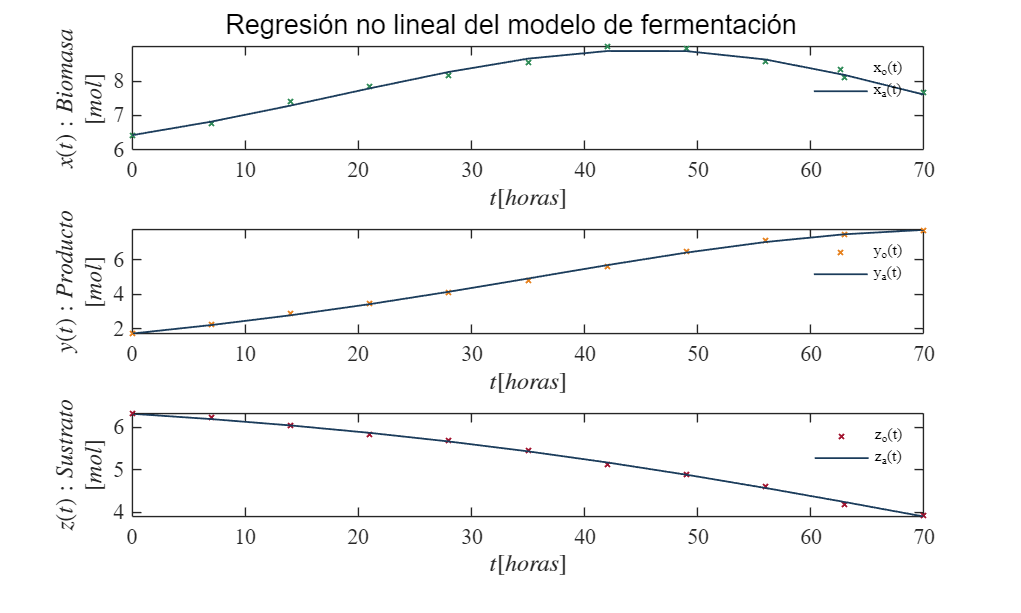


Yfit = modelFun(p_est,t);
x_fit = Yfit(1:length(t));
y_fit = Yfit(length(t)+1:2*length(t));
z_fit = Yfit(2*length(t)+1:end);

plotresults(t,xo,yo,zo,t,x_fit,y_fit,z_fit);
sgtitle('Regresión no lineal del modelo de fermentación');
exportgraphics(gcf,'regresion_no_lineal_bioestadisticos.pdf','ContentType','vector');

## Método de Heun 

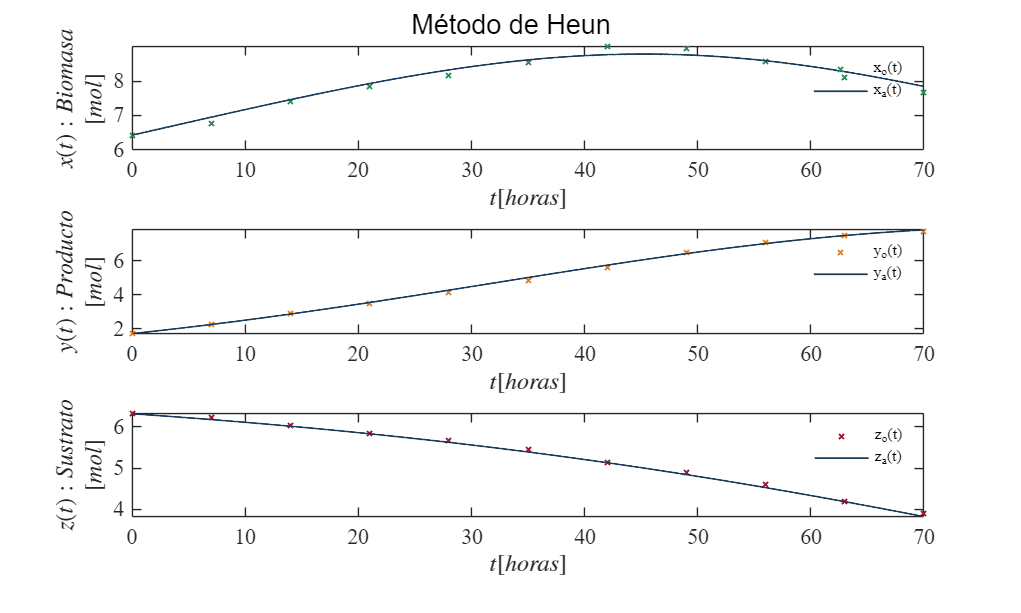

dt = 1e-4;          
tend = t(end);      


x0 = xo(1);
y0 = yo(1);
z0 = zo(1);


[th,xh,yh,zh] = sysheun(x0,y0,z0,tend,dt);


plotresults(t,xo,yo,zo,th,xh,yh,zh);
sgtitle('Método de Heun');


exportgraphics(gcf,'Heun.pdf','ContentType','vector');

## Modelo a 2t: Método de Heun 

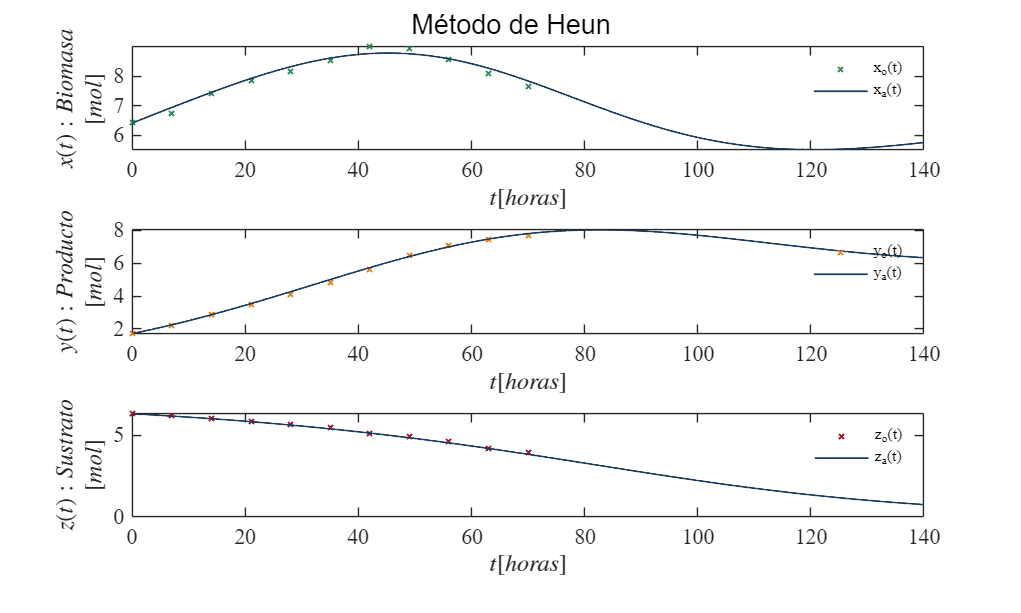

dt = 1e-4;          
tend = t(end);      


x0 = xo(1);
y0 = yo(1);
z0 = zo(1);


[th,xh,yh,zh] = sysheun(x0,y0,z0,2*tend,dt);


plotresults(t,xo,yo,zo,th,xh,yh,zh);
sgtitle('Método de Heun');


exportgraphics(gcf,'Heun2t.pdf','ContentType','vector');

## Puntos de Equilibrio del Sistema


a1 = 0.107;
a2 = 0.0296;
a3 = 0.0104;
a4 = 0.00531;

b1 = -0.1463;
b2 = 0.0375;
b3 = 0.0142;

c1 = 0.000446099478436045;
c2 = 0.00545553960134468;
c3 = 0.0381915359282955;

syms x y z

dx_dt = a1 + a2*y - a3*x - a4*y^2 == 0;
dy_dt = b1 + b2*x - b3*y == 0;
dz_dt = c1*y*z + c2*z^2 - c3*z == 0;

Sxyz = solve([dx_dt, dy_dt, dz_dt], [x, y, z]);

fprintf(['Puntos de equilibrio del sistema: ', num2str(length(Sxyz.x)), '\n']);

Puntos de equilibrio del sistema: 4



E_sym = [Sxyz.x, Sxyz.y, Sxyz.z];

disp('Puntos de equilibrio simbólicos:')

Puntos de equilibrio simbólicos:


disp(E_sym)

$$\begin{array}{l} \left(\begin{array}{ccc} \frac{71928919}{14934375}-\sigma_{1} & \frac{96232}{39825}-\sigma_{2} & 0\\ \sigma_{1}+\frac{71928919}{14934375} & \sigma_{2}+\frac{96232}{39825} & 0\\ \sigma_{4}+\frac{71928919}{14934375} & \sigma_{3}+\frac{96232}{39825} & \frac{227209910790457623839}{33398885395066344570}-\sigma_{5}\\ \frac{71928919}{14934375}-\sigma_{4} & \frac{96232}{39825}-\sigma_{3} & \sigma_{5}+\frac{227209910790457623839}{33398885395066344570} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{284\,\sqrt{7275313381}}{14934375}\\ \sigma_{2}=\frac{2\,\sqrt{7275313381}}{39825}\\ \sigma_{3}=\frac{2\,\sqrt{2471667282073451621478374330965053538914734781895569181}}{734048805537857420680617675}\\ \sigma_{4}=\frac{284\,\sqrt{2471667282073451621478374330965053538914734781895569181}}{275268302076696532755231628125}\\ \sigma_{5}=\frac{10297\,\sqrt{2471667282073451621478374330965053538914734781895569181}}{46218053454441365979944730774360} \end{array}$$


E_num = double(E_sym);

disp('Puntos de equilibrio numéricos:')

Puntos de equilibrio numéricos:


disp(E_num)

    3.1943   -1.8671         0
    6.4384    6.6999         0
    6.4384    6.6999    6.4527
    3.1943   -1.8671    7.1532



El sistema generó cuatro puntos de equilibrio. Sin embargo, no todos poseen interpretación física dentro del proceso de fermentación, ya que algunos presentan valores negativos de concentración. Por esta razón, se consideraron principalmente los puntos con variables no negativas o positivas. El equilibrio con z=0 representa una condición de frontera asociada al agotamiento del sustrato, mientras que el equilibrio con "x", "y" y "z" positivos representa un estado físicamente admisible del sistema.

## Matriz Jacobiana

syms x y z

dx_dt = (0.107 + 0.0296*y) - 0.0104*x - 0.00531*y^2;
dy_dt = -0.1463 + 0.0375*x - 0.0142*y;
dz_dt = 0.000446099478436045*y*z + 0.00545553960134468*z^2 - 0.0381915359282955*z;

J = jacobian([dx_dt, dy_dt, dz_dt], [x, y, z]);

fprintf('Matriz Jacobiana del sistema:\n'); disp(J);

Matriz Jacobiana del sistema:


$$\left(\begin{array}{ccc} -\frac{13}{1250} & \frac{37}{1250}-\frac{531\,y}{50000} & 0\\ \frac{3}{80} & -\frac{71}{5000} & 0\\ 0 & \frac{8229082910125035\,z}{18446744073709551616} & \frac{8229082910125035\,y}{18446744073709551616}+\frac{6289808925624547\,z}{576460752303423488}-\frac{5503980383212113}{144115188075855872} \end{array}\right)$$

## Estabilidad en lazo abierto

[E,lambda] = equilibria;

Equilibria  | x*         | y*         | z*         | Interpretacion 
--------------------------------------------------------------------------
eq1        (    3.1943,    -1.8671,     0.0000)   No fisico      
eq2        (    3.1943,    -1.8671,     7.1532)   No fisico      
eq3        (    6.4384,     6.6999,     0.0000)   Frontera z=0   
eq4        (    6.4384,     6.6999,     6.4527)   Fisico positivo

Matriz Jacobiana general:
[ -a3,  a2 - 2*a4*y,             0 ]
[  b2,           -b3,             0 ]
[   0,          c1*z,  c1*y + 2*c2*z - c3 ]

Jacobiana evaluada en eq1:
   -0.0104    0.0494         0
    0.0375   -0.0142         0
         0         0   -0.0390

Jacobiana evaluada en eq2:
   -0.0104    0.0494         0
    0.0375   -0.0142         0
         0    0.0032    0.0390

Jacobiana evaluada en eq3:
   -0.0104   -0.0416         0
    0.0375   -0.0142         0
         0         0   -0.0352

Jacobiana evaluada en eq4:
   -0.0104   -0.0416         0
    0.0375   -0.0142    

De los puntos de equilibrio físicamente admisibles, el equilibrio eq3=(6.4384, 6.6999, 0) se clasifica como estable, ya que todos sus valores propios tienen parte real negativa. El equilibrio eq4=(6.4384, 6.6999, 6.4527) se clasifica como inestable debido a que presenta un valor propio positivo.

## Simulink: Perturbación z(t)

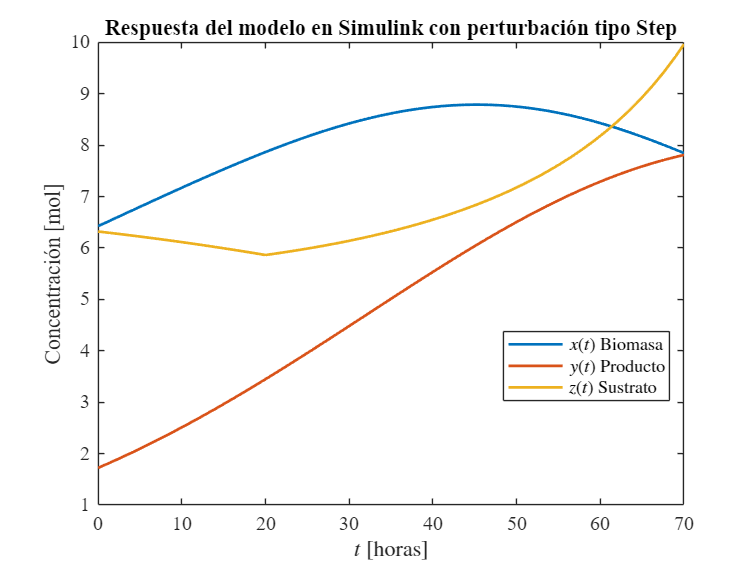

file = 'simulink_Fermentacion.slx';

out = sim(file, ...
    'StopTime','70', ...
    'Solver','ode45');

t_sim = out.t_sim;
x_sim = out.x_sim;


y_sim = out.y_sim;
z_sim = out.z_sim;

figure('Color','w');
hold on; box on; grid off;

plot(t_sim,x_sim,'LineWidth',1.5);
plot(t_sim,y_sim,'LineWidth',1.5);
plot(t_sim,z_sim,'LineWidth',1.5);

xlabel('$t$ [horas]','Interpreter','latex');
ylabel('Concentración [mol]','Interpreter','latex');

legend({'$x(t)$ Biomasa','$y(t)$ Producto','$z(t)$ Sustrato'}, ...
    'Interpreter','latex','Location','best');

title('Respuesta del modelo en Simulink con perturbación tipo Step');

set(gca,'FontName','Times New Roman','FontSize',11);

exportgraphics(gcf,'simulink_perturbacion.pdf','ContentType','vector');

**La respuesta del modelo ante una perturbación tipo Step muestra que la biomasa x****(****t****)**** aumenta hasta alcanzar un valor máximo y posteriormente disminuye ligeramente. El producto y****(****t****)**** presenta una acumulación progresiva, mientras que el sustrato z****(****t****)**** disminuye inicialmente y modifica su tendencia después de la perturbación aplicada.**

## Funciones

function plotdataraw(t,x,y,z)
set(figure(), 'color', 'w')
set(gcf, 'Units', 'Centimeters', 'Position', [1 1 25 25])
FS = 10;
mycolors = [0.0000,    0.3922,    0.3922;   
            0.9294,    0.4902,    0.1922;   
            0.5608,    0.0784,    0.2353];  

% x %
subplot (3, 3, 1); box on; hold on;
plot (t,x(:,1), 'x', 'Linewidth',1,'color', mycolors(1, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$x_1(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$x1(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,4); box on; hold on;
plot (t,x(:,2), 'x', 'Linewidth',1,'color', mycolors(1, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$x_2(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$x2(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,7); box on; hold on;
plot (t,x(:,3), 'x', 'Linewidth',1,'color', mycolors(1, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$x_3(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$x3(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

% y $
subplot (3, 3, 2); box on; hold on;
plot (t,y(:,1), 'x', 'Linewidth',1,'color', mycolors(2, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$y_1(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$y1(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,5); box on; hold on;
plot (t,y(:,2), 'x', 'Linewidth',1,'color', mycolors(2, :))
xlabel('$t  [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$y_2(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$y2(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,8); box on; hold on;
plot (t,y(:,3), 'x', 'Linewidth',1,'color', mycolors(2, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$y_3(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$y3(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

% z %
subplot (3, 3, 3); box on; hold on;
plot (t,z(:,1), 'x', 'Linewidth',1,'color', mycolors(3, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$z_1(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$z1(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,6); box on; hold on;
plot (t,z(:,2), 'x', 'Linewidth',1,'color', mycolors(3, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$z_2(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$z2(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)

subplot(3,3,9); box on; hold on;
plot (t,z(:,3), 'x', 'Linewidth',1,'color', mycolors(3, :))
xlabel('$t [horas]$','Interpreter','Latex','Fontsize',FS)
ylabel('$z_3(t)$','Interpreter','Latex','Fontsize',FS)
L = legend('$z3(t)$');
set(L, 'Interpreter', 'Latex', 'FontSize', FS, 'Location', 'NorthOutside', 'Box', 'Off', 'Orientation','Horizontal');
xlim([0 70]); xticks(0:10:70);
set(gca,'FontName','Times New Roman', 'Fontsize', FS)
end

function plotsys(to,xo,yo,zo)
   mycolors = [0.0000,    0.3922,    0.3922;  
            0.9294,    0.4902,    0.1922;   
            0.5608,    0.0784,    0.2353]; 
    set(figure(),'color','w')
    FS = 12;
    set(gcf,'Units','Centimeters','Position',[1,1,20,15])
    subplot(3,1,1)
    hold on; box on; grid off;
    plot(to,xo,'x','LineWidth',1,'MarkerSize',4,'Color', mycolors(1,:))
    xlabel('$t$ [horas]','Interpreter','Latex','FontSize',FS)
   ylabel({'$x(t): Biomasa$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,2)
    hold on; box on; grid off;
    plot(to,yo,'x','LineWidth',1,'MarkerSize',4,'Color',mycolors(2,:))
    xlabel('$t$ [horas]','Interpreter','Latex','FontSize',FS)
   ylabel({'$y(t): Producto$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
    set(gca,'FontName','Times New Roman','FontSize',FS)

    subplot(3,1,3)
    hold on; box on; grid off;
    plot(to,zo,'x','LineWidth',1,'MarkerSize',4,'Color', mycolors(3,:))
    xlabel('$t$ [horas]','Interpreter','Latex','FontSize',FS)
    ylabel({'$z(t): Sustrato$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
    set(gca,'FontName','Times New Roman','FontSize',FS)
end

function plotresults(to,xo,yo,zo,ta,xa,ya,za)
    
mycolors = [0.1059,    0.2353,    0.3569;   
            0.1843,    0.5451,    0.3412;   
            0.9020,    0.5059,    0.1176;  
            0.6353,    0.0784,    0.1843];  
set( figure(), 'Color', 'w')
FS = 12; 
set(gcf, 'Units', 'Centimeters', 'Position', [1,1,20,12])
subplot (3,1,1)
hold on; box on; grid off;
plot(to,xo,'x', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(2, :))
plot(ta, xa, '-', 'LineWidth',1, 'MarkerSize', 4, 'Color', mycolors(1, :))
xlim([0,ta(end)]);
xlabel ('$t [horas]$', 'Interpreter', 'latex', 'FontSize', FS)
ylabel({'$x(t): Biomasa$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
L = legend('x_{o}(t)', 'x_{a}(t)' );
set(L, 'FontSize', 9, 'Box','Off', 'Location', 'NorthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS)
subplot (3,1,2)
hold on; box on; grid off; 
plot(to,yo,'x', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(3,:))
plot(ta, ya, '-', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(1,:))
xlim([0,ta(end)]);
xlabel ('$t [horas]$', 'Interpreter', 'latex', 'FontSize', FS)
ylabel({'$y(t): Producto$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
L = legend('y_{o}(t)', 'y_{a}(t)' );
set(L, 'FontSize', 9, 'Box','Off', 'Location', 'NorthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS)
subplot (3,1,3)
hold on; box on; grid off; 
plot(to,zo,'x', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(4,:))
plot(ta, za, '-', 'LineWidth',1, 'MarkerSize', 4,'Color', mycolors(1,:))
xlim([0,ta(end)]);
xlabel ('$t [horas]$', 'Interpreter', 'latex', 'FontSize', FS)
ylabel({'$z(t): Sustrato$','$[mol]$'}, 'Interpreter', 'latex', 'FontSize', 8)
L = legend('z_{o}(t)', 'z_{a}(t)' );
set(L, 'FontSize', 9, 'Box','Off', 'Location', 'NorthEast');
set (gca, 'FontName', 'Times New Roman', 'FontSize', FS)

end

function plott(t,Pp0,Pp1)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [0.1059,    0.2353,    0.3569;
            0.1843,    0.5451,    0.3412;
            0.9020,    0.5059,    0.1176; 
            0.6353,    0.0784,    0.1843];
    colororder(mycolors);
    one = ones(length(Pp1),1);
    plot(t, Pp0, t, Pp1,t, one,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    L = legend('$z_{0}(t): Sin\ perturbacion$','$z_{1}(t): Con\ perturbacion$');
set(L, 'Interpreter', 'Latex', 'FontSize', 10, ...
    'Location', 'BestOutside', 'Box', 'On');
xlabel('$t$ $[horas]$', 'Interpreter', 'Latex', 'FontSize', 11);
ylabel('$z(t)$ Sustrato $[mol]$', 'Interpreter', 'Latex', 'FontSize', 10);
end

function Yfit = modelo_fermentacion_fit(p,t,x0,y0,z0)

    a1 = p(1);
    a2 = p(2);
    a3 = p(3);
    a4 = p(4);

    b1 = p(5);
    b2 = p(6);
    b3 = p(7);

    c1 = p(8);
    c2 = p(9);
    c3 = p(10);

    V0 = [x0; y0; z0];

    [~,V] = ode45(@(t,V) sistema_fermentacion(t,V,a1,a2,a3,a4,b1,b2,b3,c1,c2,c3), t, V0);

    x = V(:,1);
    y = V(:,2);
    z = V(:,3);

    Yfit = [x; y; z];

end
function dV = sistema_fermentacion(~,V,a1,a2,a3,a4,b1,b2,b3,c1,c2,c3)

    x = V(1);
    y = V(2);
    z = V(3);

    dV = zeros(3,1);

    dV(1) = a1 + a2*y - a3*x - a4*y^2;
    dV(2) = b1 + b2*x - b3*y;
    dV(3) = c1*y*z + c2*z^2 - c3*z;

end

### Datos experimentales

function [to,x,y,z,x3,y3,z3] = getdata(file)
    sys = readmatrix(file);
    to = round(sys(:,1));
    x1 = sys(:,2); y1 = sys(:,3); z1= sys(:,4);
    x2 = sys(:,5); y2 = sys(:,6); z2= sys(:,7);
    x3 = sys(:,8); y3 = sys(:,9); z3= sys(:,10);
    x = [x1,x2,x3]; y = [y1,y2,y3]; z = [z1,z2,z3];
end

### Funciones

function [to,xo,yo,zo] = getdatanorm(file,smooth,normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));

    xo = sys(:,8);
    yo = sys(:,9);
    zo = sys(:,10);

    if smooth == false && normalize == false
        return
    elseif smooth == true && normalize == false
        xo = smoothdata(xo,'gaussian',5);
        yo = smoothdata(yo,'gaussian',5);
        zo = smoothdata(zo,'gaussian',5);
    elseif smooth == false && normalize == true
        to = to - to(1);
        xo = xo/max(xo);
        yo = yo/max(yo);
        zo = zo/max(zo);
    elseif smooth == true && normalize == true
        to = to - to(1);
        xo = xo/max(xo);
        yo = yo/max(yo);
        zo = zo/max(zo);
        xo = smoothdata(xo,'gaussian',5);
        yo = smoothdata(yo,'gaussian',5);
        zo = smoothdata(zo,'gaussian',5);
    end
end


## Función Heun

function [t,x,y,z] = sysheun(x0,y0,z0,tend,dt)

    n = round(tend/dt);
    t = (0:dt:tend)';

    x = zeros(length(t),1);
    y = zeros(length(t),1);
    z = zeros(length(t),1);

    x(1) = x0;
    y(1) = y0;
    z(1) = z0;

    for i = 1:n

        [fx,fy,fz] = f(x(i),y(i),z(i));

        xp = x(i) + fx*dt;
        yp = y(i) + fy*dt;
        zp = z(i) + fz*dt;

        [fxp,fyp,fzp] = f(xp,yp,zp);

        x(i+1) = x(i) + (fx + fxp)*dt/2;
        y(i+1) = y(i) + (fy + fyp)*dt/2;
        z(i+1) = z(i) + (fz + fzp)*dt/2;

    end

    function [dx,dy,dz] = f(x,y,z)

    dx = 0.107 + 0.0296*y - 0.0104*x - 0.00531*y^2;

    dy = -0.1463 + 0.0375*x - 0.0142*y;

    dz = 0.000446099478436045*y*z ...
       + 0.00545553960134468*z^2 ...
       - 0.0381915359282955*z;

end

end

## Equilibrios

 function [E,lambda] = equilibria


a1 = 0.107;
a2 = 0.0296;
a3 = 0.0104;
a4 = 0.00531;

b1 = -0.1463;
b2 = 0.0375;
b3 = 0.0142;

c1 = 0.000446099478436045;
c2 = 0.00545553960134468;
c3 = 0.0381915359282955;


e1 = [3.194309; -1.867141; 0.000000];
e2 = [3.194309; -1.867141; 7.153182];
e3 = [6.438356; 6.699884; 0.000000];
e4 = [6.438356; 6.699884; 6.452656];

E = [e1,e2,e3,e4];
E = double(E)';
E(E > -1e-12 & E < 1e-12) = 0;

names = {'eq1';'eq2';'eq3';'eq4'};

fprintf('%-11s | %-10s | %-10s | %-10s | %-15s\n', ...
    'Equilibria', 'x*', 'y*', 'z*', 'Interpretacion');
fprintf('--------------------------------------------------------------------------\n');

for i = 1:size(E,1)

    if all(E(i,:) > 0)
        interp = 'Fisico positivo';
    elseif E(i,1) > 0 && E(i,2) > 0 && E(i,3) == 0
        interp = 'Frontera z=0';
    else
        interp = 'No fisico';
    end

    fprintf('%-10s (%10.4f, %10.4f, %10.4f)   %-15s\n', ...
        names{i}, E(i,1), E(i,2), E(i,3), interp);
end


lr = zeros(size(E,1),3);
li = zeros(size(E,1),3);
stability = cell(size(E,1),1);

fprintf('\nMatriz Jacobiana general:\n');
fprintf('[ -a3,  a2 - 2*a4*y,             0 ]\n');
fprintf('[  b2,           -b3,             0 ]\n');
fprintf('[   0,          c1*z,  c1*y + 2*c2*z - c3 ]\n\n');

for i = 1:size(E,1)

    x = E(i,1);
    y = E(i,2);
    z = E(i,3);

  
    J = [ -a3,  a2 - 2*a4*y,                 0;
           b2,            -b3,                 0;
            0,            c1*z,  c1*y + 2*c2*z - c3 ];

    eigJ = eig(J);

    lr(i,:) = real(eigJ);
    li(i,:) = imag(eigJ);

    lr(lr > -1e-12 & lr < 1e-12) = 0;

    if all(lr(i,:) < 0)
        stability{i,1} = 'stable';
    elseif any(lr(i,:) > 0)
        stability{i,1} = 'unstable';
    else
        stability{i,1} = 'unidentified';
    end

    fprintf('Jacobiana evaluada en %s:\n', names{i});
    disp(J);

end

lambda = lr + 1i*li;

fprintf('\n\n%-10s | %-18s | %-18s | %-18s | %-10s\n', ...
    'Equilibria', 'lambda 1', 'lambda 2', 'lambda 3', 'stability');
fprintf('---------------------------------------------------------------------------------------------\n');

for i = 1:size(E,1)
    fprintf('%-10s %+.4e%+.4ei   %+.4e%+.4ei   %+.4e%+.4ei   %-10s\n', ...
        names{i}, ...
        real(lambda(i,1)), imag(lambda(i,1)), ...
        real(lambda(i,2)), imag(lambda(i,2)), ...
        real(lambda(i,3)), imag(lambda(i,3)), ...
        stability{i});
end

end